clear arduino;

    %connect to serial, re-run untill light tunrs on
    arduino = serialport("COM7", 115200);
    configureTerminator(arduino,"LF");

done


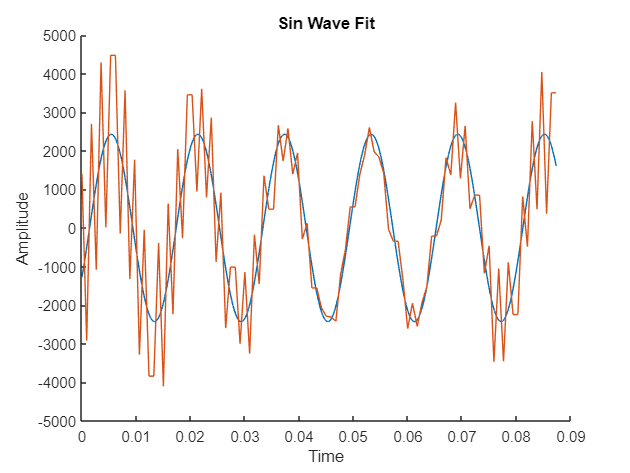

Phase: 321.9933deg
STD: 1.7684deg


phase_range =   320.0808  324.0450


[phase, amp] = collect_sample(arduino, true);

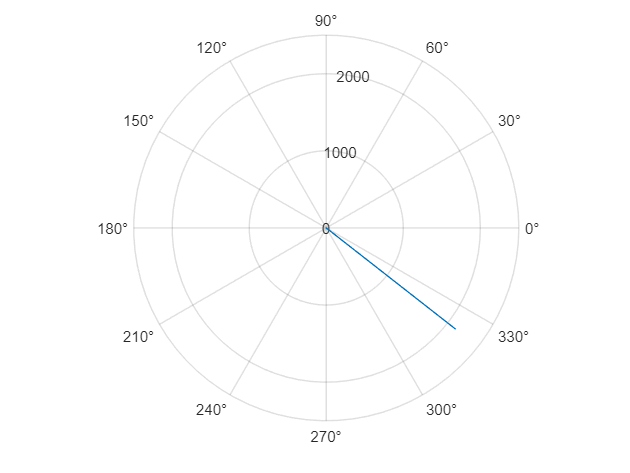

polarplot([0 phase], [0 amp])

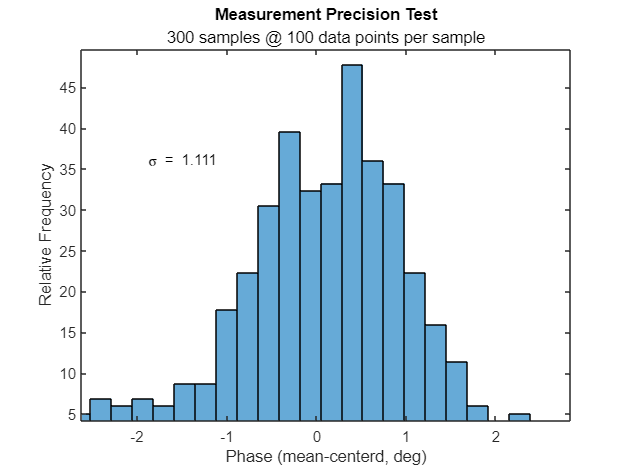


histogram(phase_test - mean(phase_test), 60)
xlim([-3 3])
title("Measurement Precision Test")
subtitle("300 samples @ 100 data points per sample")
xlabel("Phase (mean-centerd, deg)")
ylabel("Relative Frequency")
text(-2.2, 35, '\sigma = ' + string(round(std(phase_test), 3)))


std(phase_test(end-50:end))

ans = 1.0682


%polarplot([0 phase], [0 amp], "Linewidth", 1)








num_data_points = 500;
configureCallback(arduino, "off");
    %set up data struct to read
    arduino.UserData = struct("Data",zeros(num_data_points,3),"Count",1, "Points", num_data_points);
    
    serial_command(arduino, num_data_points/10);
    configureTerminator(arduino,"CR");
    flush(arduino);
    configureCallback(arduino,"terminator", @read_data);


    %clear arduino


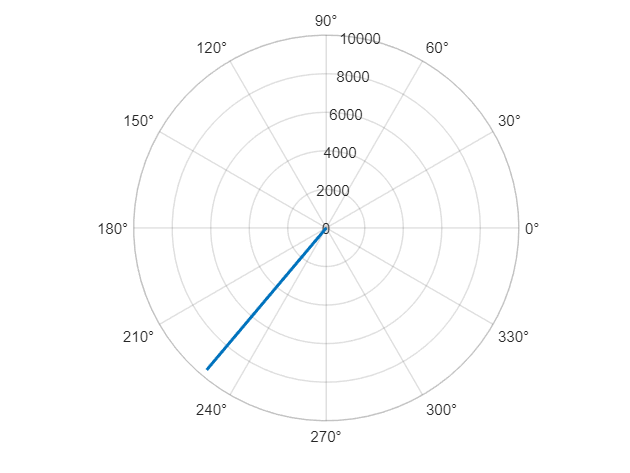

configureCallback(arduino, "off");
    arduino.UserData.Data;
figure(1)
clf
%plot(arduino.UserData.Data(:,1)/100000,arduino.UserData.Data(:,2))
data_array=[(arduino.UserData.Data(:,1)-arduino.UserData.Data(1,1))./1000000    arduino.UserData.Data(:,2)  (arduino.UserData.Data(:,3)-arduino.UserData.Data(1,1))./1000000];
[phase, amp] = compute_phase(data_array);
figure()
clf
polarplot([0 phase], [0 amp], "Linewidth", 2);

data_array(:,3) = (data_array(:,3) - data_array(1,1))./1000000;
data_array(:,1) = (data_array(:,1) - data_array(1,1))./1000000;



dt = [];
for i = 2:length(data_array(:,1))

    dt(end+1)= data_array(i,1) - data_array(i-1,1);
end
dt = mean(dt)

dt = 8.7736e-04

rpm = [];
for i = 2:length(data_array(:,1))
    if data_array(i,3) ~= data_array(i-1,3)
    rpm(end+1)= data_array(i,3) - data_array(i-1,3);
    end
end
 rpm_frequ = 1 / (mean(rpm))

rpm_frequ = 76.7222

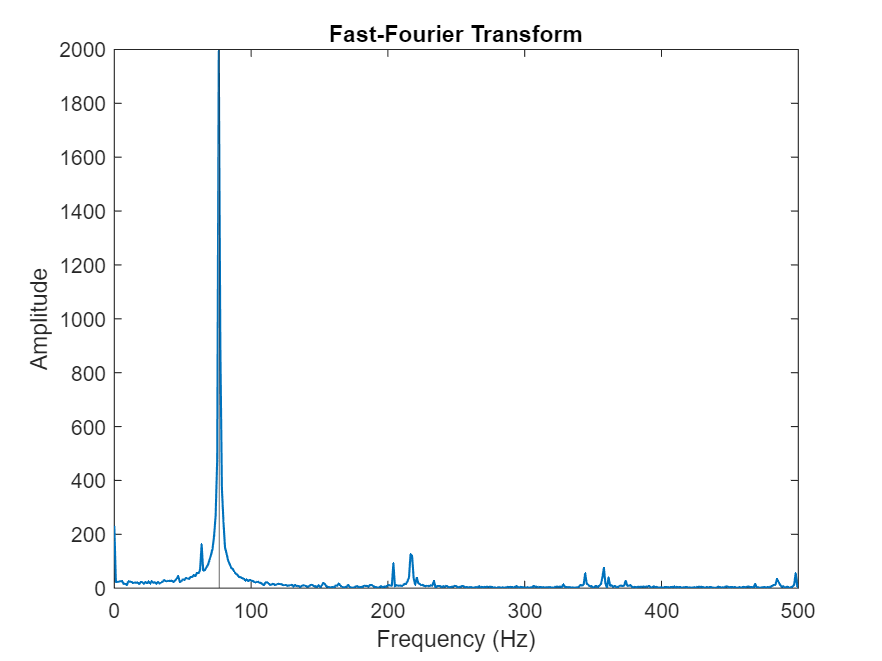

figure(3)
clf
Y = fft(data_array(:,2));
Fs = 1/dt;
T = 1/Fs;
L = length(data_array(:,1));

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1, "Linewidth", 1)
xlim([0,500])
xlabel("Frequency (Hz)")
ylabel("Amplitude")
xline(rpm_frequ)
title("Fast-Fourier Transform")

p =fit_sin(data_array(:,1), data_array(:,2), [2000 rpm_frequ*2*pi -pi/2])

p = 1.0e+03 *

    2.3492    0.4821   -0.0010


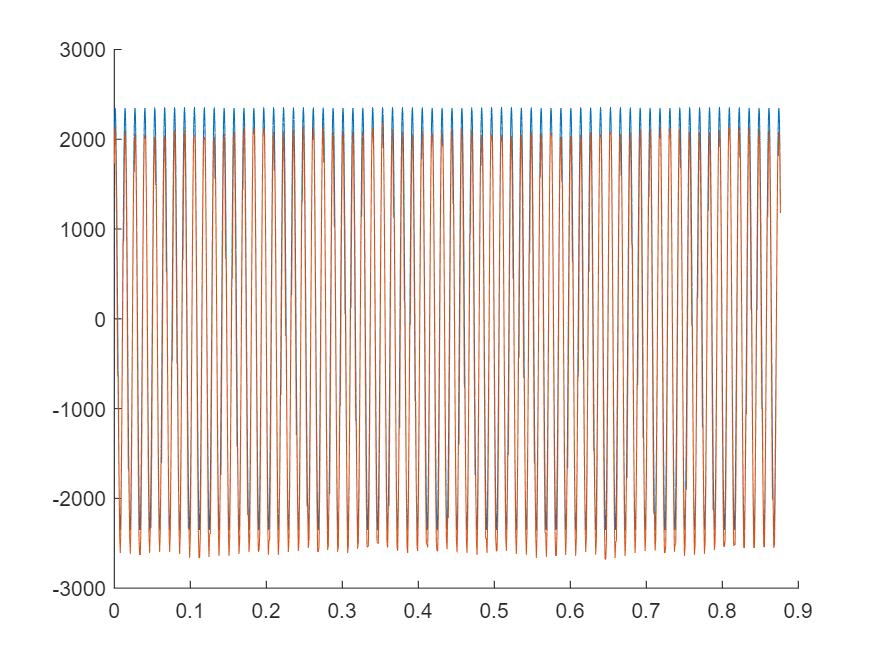

t_vec = linspace(0, data_array(end,1), 100000);
clf
hold on
plot(t_vec, p(1).*sin(p(2).*t_vec - p(3)))
plot(data_array(:,1), data_array(:,2))

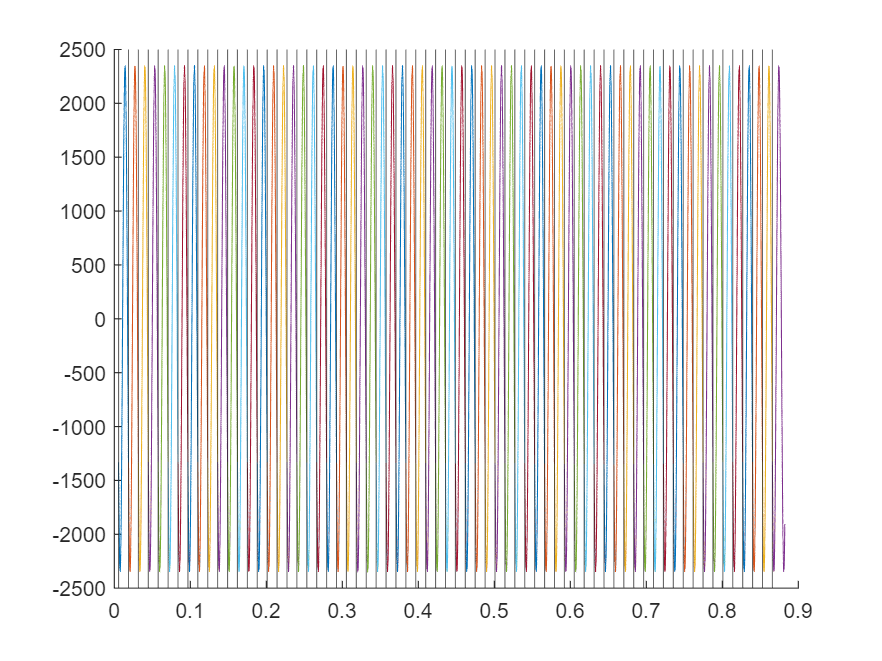

phase_angle = [];
figure(10)
clf
hold on


for i=2:length(data_array(:,1))
    if(data_array(i,3) ~= data_array(i-1,3))
        xline(data_array(i,3))


        t_0 = data_array(i,3);
        observation_range = 1/rpm_frequ;
        time_range = linspace(data_array(i,3), data_array(i,1) + (observation_range * 1.25), 1000);
        observation_data = p(1) .* sin(p(2) .* time_range - p(3));
        plot(time_range, observation_data);
        [val, idx] = max(p(1) .* sin(p(2) .* time_range - p(3)));
        phase_time = time_range(idx) - t_0;
        phase_angle(end+1) = phase_time * (rpm_frequ * 360);

        
    end
end
hold off


mean_phase = mean(phase_angle)

mean_phase = 235.3543

std(phase_angle)

ans = 0.2392

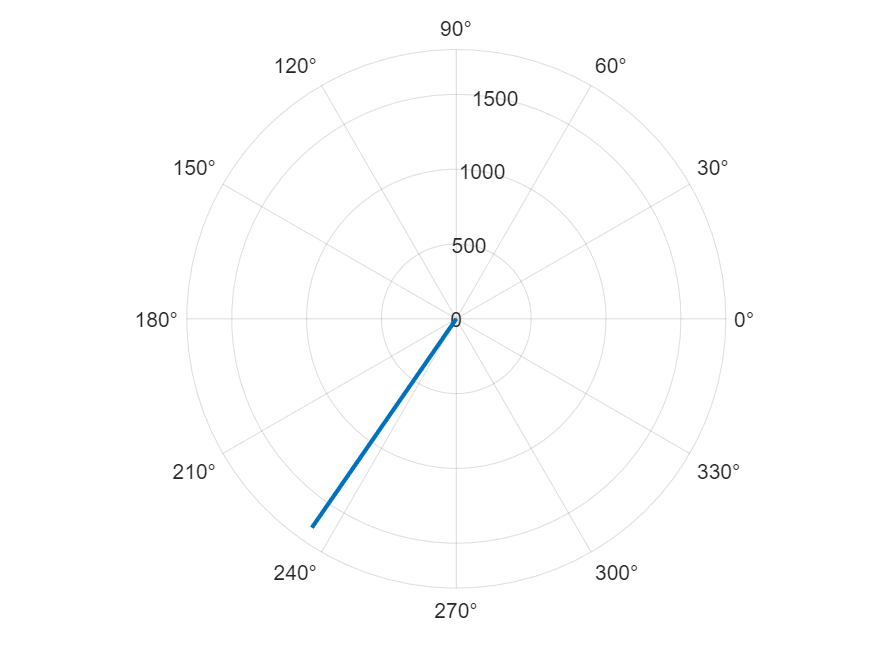

figure()
clf
polarplot([0 deg2rad(mean_phase)], [0 rms(data_array(:,2))], "Linewidth", 2)

serialportlist("available")

ans = "COM3"

clf
h = animatedline('MaximumNumPoints',100);
axis([0,4*pi,-1,1])

x = linspace(0,4*pi,1000);
y = sin(x);
for k = 1:length(x)
    addpoints(h,x(k),y(k));
    drawnow
end

figure(1)
clf
plot(arduino.UserData.Data(good_data,1),arduino.UserData.Data(good_data,2))


clear arduino

clear arduino


    %connect to serial
    arduino = serialport("COM7",9600);
    %set up line terminator
    configureTerminator(arduino,"CR/LF");
    %clear serial buffer
    flush(arduino);
    %set up data struct to read
    arduino.UserData = struct("Data",[],"Count",1);
    %run func. every time the "terminator
    % is detected


  configureCallback(arduino,"terminator", @read_data);
    


    

    function sample_data(src, ~)

    % Read the ASCII data from the serialport object.
    readline(src)
    end


    function read_data(src, ~)

    % Read the ASCII data from the serialport object.

    data = readline(src);

    data = split(data);
    data = str2double(data);

     %Convert the string data to numeric type and save it in the UserData
     %property of the serialport object.
     src.UserData.Data(src.UserData.Count,:) = [data(1) data(2) data(3)];
 
     % Update the Count value of the serialport object.
     src.UserData.Count = src.UserData.Count + 1;

  
     % If 1001 data points have been collected from the Arduino, switch off the
     % callbacks and plot the data.
         if src.UserData.Count > src.UserData.Points
            configureCallback(src, "off");

            data_array=[(src.UserData.Data(:,1)-src.UserData.Data(1,1))./1000000    src.UserData.Data(:,2)  (src.UserData.Data(:,3)-src.UserData.Data(1,1))./1000000];
            [phase, amp] = compute_phase(data_array);
            polarplot([0 phase], [0 amp], "Linewidth", 1);






            
         end
    end

